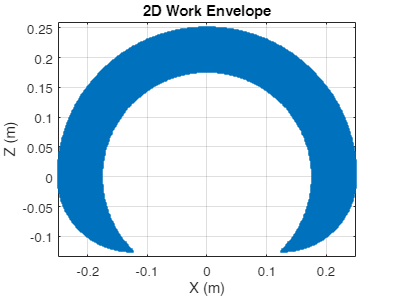

syms theta1 theta2 real
% DH parameters: [a, alpha, d, theta]
dh_params = [0.125 0 0 theta1; 0.125 0 0 theta2];

% Joint ranges
theta1_range = linspace(0, pi, 180);
theta2_range = linspace(-pi/2, pi/2, 180);

% Map for the joint ranges
joint_ranges = containers.Map({'theta1', 'theta2'}, {theta1_range, theta2_range});

% Plot the 2D workspace
plot2dworkspace(dh_params, joint_ranges);


function plot2dworkspace(dh_params, joint_ranges)
    [theta1_vals, theta2_vals] = ndgrid(joint_ranges('theta1'), joint_ranges('theta2'));
    x_vals = dh_params(2, 1) * cos(theta1_vals) + dh_params(2, 1) * cos(theta1_vals + theta2_vals);
    y_vals = dh_params(2, 1) * sin(theta1_vals) + dh_params(2, 1) * sin(theta1_vals + theta2_vals);
    plot(x_vals(:), y_vals(:), '.');
    xlabel('X (m)');
    ylabel('Z (m)');
    title('2D Work Envelope');
    axis equal;
    grid on
end